# Finite Impulse Response (FIR) Filtering

## Generate kernel properties

sample_rate = 1024;
nyquist = sample_rate/2; % see nyquist theorem
band_pass = [20 45]; %the desired frequencies
transition = .1; %transition zone of filter
order = 5; % play with a value between 1 and 20 for example
order = round(5*sample_rate/band_pass(1));
kernel_y = [0 0 1 1 0 0];
kernel_x = [0 band_pass(1)-band_pass(1)*transition band_pass(1) band_pass(2) band_pass(2)+band_pass(2)*transition nyquist];

## Generate a kernel with firls

- firls [https://www.mathworks.com/help/signal/ref/firls.html](https://www.mathworks.com/help/signal/ref/firls.html)  

freqs = kernel_x / nyquist;
kernel = firls(order, freqs, kernel_y);
kernel_powers = abs(fft(kernel)).^2;
hz_vals = linspace(0, nyquist, floor(length(kernel)/2)+1);
kernel_powers = kernel_powers(1:length(hz_vals));

## Generate a kernel with fir1

- [https://www.mathworks.com/help/signal/ref/fir1.html](https://www.mathworks.com/help/signal/ref/fir1.html)  

kernel2 = fir1(order, band_pass/nyquist);
kernel_powers2 = abs(fft(kernel2)).^2;
kernel_powers2 = kernel_powers2(1:length(hz_vals));

## Plot the kernels

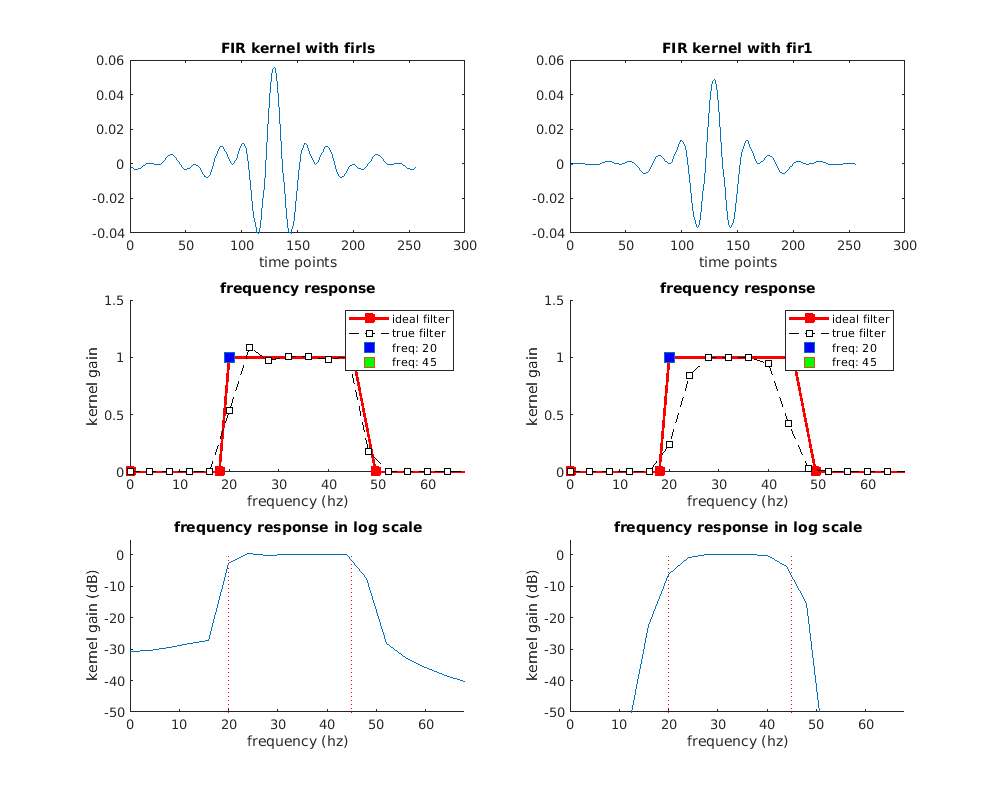

f1 = figure(1); clf;
f1.Position = [0 0 1000 800];
subplot(321);
plot(kernel);
ylim([-.04 .06]);
xlabel("time points");
title("FIR kernel with firls");

subplot(323);
hold on;
plot(kernel_x, kernel_y, 'rs-', 'linew', 2, 'markersize', 8, 'markerfacecolor', 'r');
plot(hz_vals, kernel_powers, 'ks--', 'markerfacecolor', 'w');
plot(band_pass(1), 1, 's', 'markerfacecolor', 'b', 'markersize', 10);
plot(band_pass(2), 1, 's', 'markerfacecolor', 'g', 'markersize', 10);
xlim([0 kernel_x(5)+kernel_x(2)]); %for centering
ylim([0 1.5]);
title("frequency response");
xlabel("frequency (hz)");
ylabel("kernel gain");
legend(["ideal filter", "true filter", "freq: " + num2str(band_pass(1)), "freq: " + num2str(band_pass(2))]);
hold off;

subplot(325);
hold on;
plot(hz_vals, 10*log10(kernel_powers));
plot([1 1]*band_pass(1), get(gca, 'ylim'), 'r:');
plot([1 1]*band_pass(2), get(gca, 'ylim'), 'r:');
xlim([0 68]);
ylim([-50 5]);
title("frequency response in log scale");
xlabel("frequency (hz)");
ylabel("kernel gain (dB)");

subplot(322);
plot(kernel2);
xlabel("time points");
title("FIR kernel with fir1");

subplot(324);
hold on;
plot(kernel_x, kernel_y, 'rs-', 'linew', 2, 'markersize', 8, 'markerfacecolor', 'r');
plot(hz_vals, kernel_powers2, 'ks--', 'markerfacecolor', 'w');
plot(band_pass(1), 1, 's', 'markerfacecolor', 'b', 'markersize', 10);
plot(band_pass(2), 1, 's', 'markerfacecolor', 'g', 'markersize', 10);
xlim([0 kernel_x(5)+kernel_x(2)]); %for centering
ylim([0 1.5]);
title("frequency response");
xlabel("frequency (hz)");
ylabel("kernel gain");
legend(["ideal filter", "true filter", "freq: " + num2str(band_pass(1)), "freq: " + num2str(band_pass(2))]);
hold off;

subplot(326);
hold on;
plot(hz_vals, 10*log10(kernel_powers2));
plot([1 1]*band_pass(1), get(gca, 'ylim'), 'r:');
plot([1 1]*band_pass(2), get(gca, 'ylim'), 'r:');
xlim([0 68]);
ylim([-50 5]);
title("frequency response in log scale");
xlabel("frequency (hz)");
ylabel("kernel gain (dB)");

### Create a signal

- gaussian based signal

N = 500;
hz_vals = linspace(0, 1, N);
gaussian = exp(-(4*log(2)*(hz_vals-.1)/.1).^2)*N/2;
signal = real(ifft(gaussian.*exp(1i*rand(1,N)*2*pi))) + randn(1,N);

- generate a zero-phase-shift low pass filter with fir1

- [https://www.youtube.com/watch?v=ue4ba_wXV6A](https://www.youtube.com/watch?v=ue4ba_wXV6A) 

- manually you filter forward, then reverse, then flip it back forward

kernel3 = fir1(150, .6, 'low');
filtered = filter(kernel3, 1, signal); %filter forward
filtered = filter(kernel3, 1, filtered(end:-1:1)); %filter in reverse
filtered = filtered(end:-1:1); %reverse the signal back forward

- Plot the signal and its power spectrum

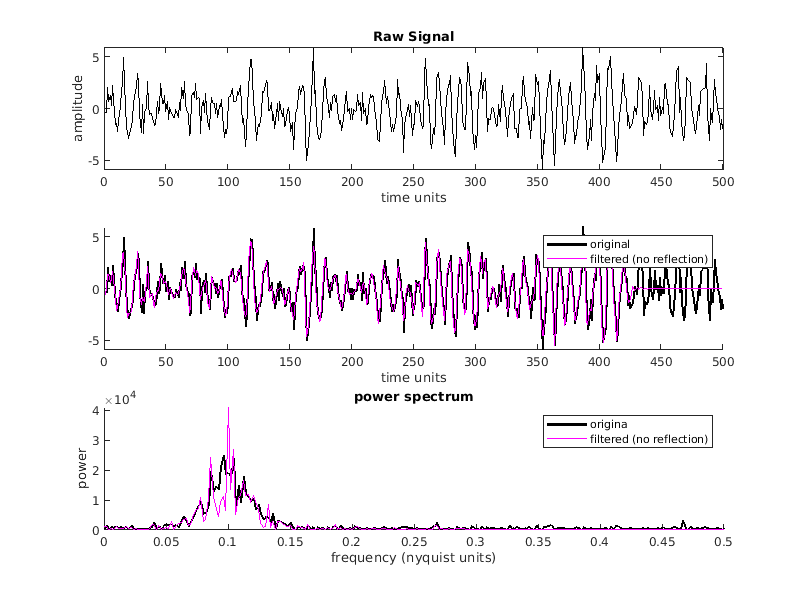

f2 = figure(2); clf;
f2.Position = [0 0 800 600];
subplot(311);
plot(1:N, signal, 'k');
xlim([0 N+1]);
title("Raw Signal");
xlabel("time units");
ylabel("amplitude");

subplot(312);
hold on;
plot(1:N, signal, 'k', 'linew', 2);
plot(1:N, filtered, 'm');
xlim([0 N+1]);
xlabel("time units");
legend({"original", "filtered (no reflection)"});

subplot(313);
hold on;
plot(hz_vals, abs(fft(signal)).^2, 'k', 'linew', 2);
plot(hz_vals, abs(fft(filtered)).^2, 'm');
xlim([0 .5]);
title("power spectrum");
xlabel("frequency (nyquist units)");
ylabel("power");
legend({"origina", "filtered (no reflection)"});

- Notice the flat line in the filtered signal, and the power spectrums don't match?

- Due to edge effects!

### Perform reflection to remove edge effects

- reflect the edges of the signal